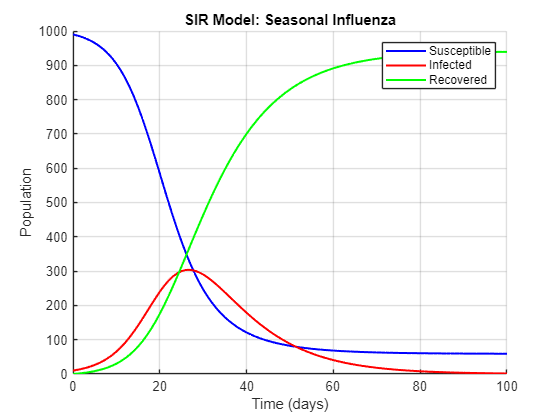

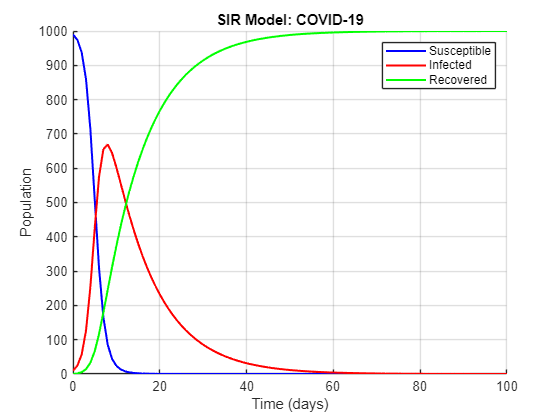

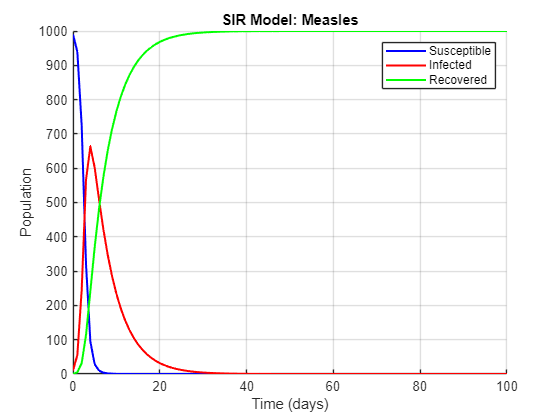

% Dummy Variable. Added by Ryan.
% Sets up a flag that allows Q4.m to end this script before the plots are
% made.
Q4_flag(2) = 0;

% Parameters
T = 100; % Total simulation time (days)
h = 1; % Time step (days)
N = 1000; % Total population (constant)
S0 = 990; % Initial susceptible population
I0 = 10; % Initial infected population
R0 = 0; % Initial recovered population

% Parameter sets for different diseases
parameters = [
    0.3, 0.1;  % Seasonal Influenza (β, γ)
    1.0, 0.1;  % COVID-19 (β, γ)
    2.0, 0.2   % Measles (β, γ)
            ];
disease_names = {'Seasonal Influenza', 'COVID-19', 'Measles'};

for k = 1:size(parameters, 1)
    beta = parameters(k, 1);
    gamma = parameters(k, 2);

    S = zeros(1, T+1); I = zeros(1, T+1); R = zeros(1, T+1);
    S(1) = S0; I(1) = I0; R(1) = R0;

    % RK4 method
    for t = 1:T
        % Current values
        S_t = S(t); I_t = I(t); R_t = R(t);

        % Define ODEs
        dS = @(S, I) -(beta / N) * S * I;
        dI = @(S, I) (beta / N) * S * I - gamma * I;
        dR = @(I) gamma * I;

        % RK4 coefficients
        k1_S = h * dS(S_t, I_t);
        k1_I = h * dI(S_t, I_t);
        k1_R = h * dR(I_t);

        k2_S = h * dS(S_t + k1_S/2, I_t + k1_I/2);
        k2_I = h * dI(S_t + k1_S/2, I_t + k1_I/2);
        k2_R = h * dR(I_t + k1_I/2);

        k3_S = h * dS(S_t + k2_S/2, I_t + k2_I/2);
        k3_I = h * dI(S_t + k2_S/2, I_t + k2_I/2);
        k3_R = h * dR(I_t + k2_I/2);

        k4_S = h * dS(S_t + k3_S, I_t + k3_I);
        k4_I = h * dI(S_t + k3_S, I_t + k3_I);
        k4_R = h * dR(I_t + k3_I);
        
        S(t+1) = S_t + (k1_S + 2*k2_S + 2*k3_S + k4_S) / 6;
        I(t+1) = I_t + (k1_I + 2*k2_I + 2*k3_I + k4_I) / 6;
        R(t+1) = R_t + (k1_R + 2*k2_R + 2*k3_R + k4_R) / 6;
    end

% This was added by Ryan. This makes it so that Q4.m can run this script
% without also importing/displaying any plots/figures.
if Q4_flag(1) == 1
    return
end

    % Plot results
    figure;
    hold on;
    plot(0:T, S, 'b', 'LineWidth', 1.5);
    plot(0:T, I, 'r', 'LineWidth', 1.5);
    plot(0:T, R, 'g', 'LineWidth', 1.5);
    title(['SIR Model: ', disease_names{k}]);
    xlabel('Time (days)');
    ylabel('Population');
    legend('Susceptible', 'Infected', 'Recovered');
    grid on;
    hold off;
end

A higher transmission rate such as, Measles with beta=2 causes a rapid increase in infections, leading to a sharp peak in I(t). This makes the disease spread quickly through the susceptible population, depleting S(t) rapidly. A lower recovery rate prolongs the duration of infection, keeping I elevated for longer periods like COVID-19 with Gamma=0.1 Diseases with higher beta/gamma ratios, the basic reproduction number R_0, spread more aggressively and involve larger portions of the population before fading. In conclusion, the measles virus spreads quickly due to its high beta, but it has a fast recovery so it limits its time of infection. Covid-19 has a slower spread but a longer infection period which reflects its beta=1 and gamma=0.1. The seasonal Influenza has a moderate gamma and beta so it is slower and less dramatic all around.